## Calcium Analysis

**Clear the workspace**

clear all
clc

Import excel spreadsheet from NIS Elements with data, in the following format: 

Frame    Cell 1    Cell 2    Etc

1            Value    Value    Value

2            Value    Value    Value

File = uigetfile('*.xlsx');
[Pre_data, Pre_headers] = xlsread(File);
Pre_headers = Pre_headers(2,:);
Data = Pre_data(:,3:end-1);
Data_headers = Pre_headers(1, 3:end-1);
Frame_column = Pre_data(:,1);
Frame_header = Pre_headers(1,1);
Time_column = Pre_data(:,2);
Time_header = Pre_headers(1,2);
[NumberofRows, NumberofColumns] = size(Data);
Max_value = max(max(Data));
Pre_time = datestr(Time_column, 'MM:SS:FFF');
Time = cellstr(Pre_time);

**Select cell type and treatment**

fps = round(str2double(inputdlg('What is the fps rate?')));

**Plot Raw Data**

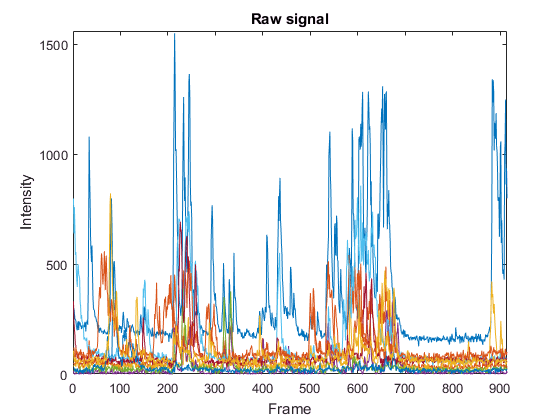

Figure1 = figure;
plot(Frame_column, Data)
axis([0 NumberofRows 0 Max_value+10])
title('Raw signal')
ylabel('Intensity')
xlabel('Frame')

**Plot Individual Signal**

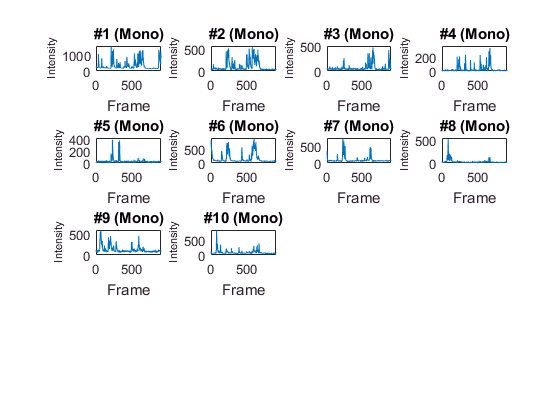

%Find out number dimension of figure for subplots
% according to how many columns there are, by
% finding the square root of the # of columns,
% approximated by ceil function

Dimensionofsubplots = ceil(sqrt(NumberofColumns));
Figure2 = figure;
for i = 1:NumberofColumns
    subplot1 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(Data(:,i));
    
    %plot specifications
    Max_value_subplot = max(max(Data(:,i)));
    axis([0 NumberofRows 0 Max_value_subplot+30]);
    title(Data_headers(i));
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 8)
    hold off
end

**Calculate the baseline for DF/F (average of first second (or 8 frames))**

Mean = mean(Data(710:720, :));

%plot specifications
Cell_ID = Data_headers;
Average_first_8_frames = Mean';
Table_1 = table(Cell_ID, Average_first_8_frames)

Error using tabular/countVarInputs (line 227)
All variables must have the same number of rows.

Error in table (line 208)
                [numVars,numRows] = tabular.countVarInputs(varargin);

## **Calculate dF/F (normalized data)**

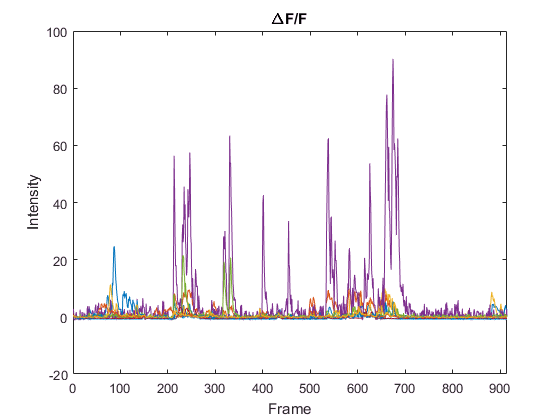

DeltaFoverF = (Data - Mean)./Mean;

% Finds hidden mistakes in DF/F
for i = 1:NumberofColumns
    for j = 1:NumberofRows
        if DeltaFoverF(j,i)==9 | isnan(DeltaFoverF(j,i))
           error('Something is wrong')          
        end
    end
end

Figure3 = figure;
plot(DeltaFoverF)
%plot specifications
axis([0 NumberofRows ylim])
title('\DeltaF/F');
xlabel('Frame');
ylabel('Intensity');

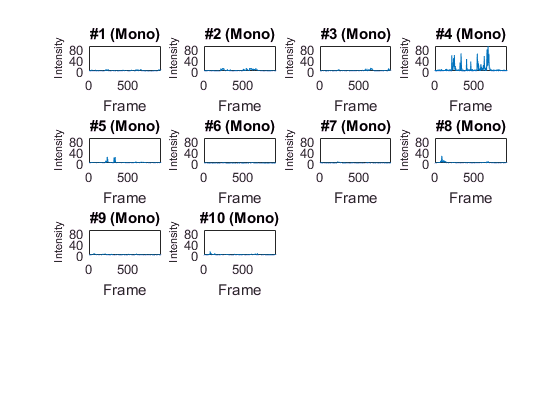



%Plot DeltaFoverF of each cell
Figure4 = figure;
for i = 1:NumberofColumns
    subplot1 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(DeltaFoverF(:,i));
    
    %plot specifications
    Max_value_subplot = max(max(DeltaFoverF(:,i)));
    title(Data_headers(i));
    axis([0 NumberofRows min(min(DeltaFoverF)) max(max(DeltaFoverF))])
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 8)
    hold off
end

**Smooth data (temporal smoothing, window size = 1 second)**

window = ones(fps,1)/fps;
Smoothed = convn(DeltaFoverF, window, 'same');
Figure5 = figure;
plot(Smoothed)

%Plot Smoothed data of each cell
Figure5 = figure;
for i = 1:NumberofColumns
    subplot2 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(Smoothed(:,i));
    
    %plot specifications
    Max_value_subplot = max(max(Smoothed(:,i)));
    title(Data_headers(i));
    axis([0 NumberofRows min(min(Smoothed)) max(max(Smoothed))]);
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 8)
    hold off
end

**Calculate the standard deviation of ****previous 10 frames**

StdDev = movstd(DeltaFoverF, [9 0]);
StdDevPrevious10 = StdDev(10:end, :);
StdDev = 2.5 .* StdDevPrevious10;      % Creates array with values of 2.5*STD of 10 previous frames


**Find all peaks and valleys in DF/F**

%finds all peaks and all valleys in Smoothed DF/F
for i = 1:NumberofColumns
    [allpeaks{i}, allpeaklocs{i}] = findpeaks(+Smoothed(:,i));
    [allvalleys{i}, allvalleylocs{i}] = findpeaks(-Smoothed(:,i));
    allvalleysneg{1,i} = -allvalleys{1,i};
end

%example in graph of all peaks and valleys in column 1
plot(Frame_column, Smoothed(:,1))
hold on
plot(allpeaklocs{1,1}, allpeaks{1,1}, '*m');
plot(allvalleylocs{1,1}, allvalleysneg{1,1}, 'sq');
hold off

%all graphs of all peaks and valleys
Figure6 = figure;
for i = 1:NumberofColumns
    subplot2 = subplot(Dimensionofsubplots, Dimensionofsubplots, i);
    plot(Frame_column, Smoothed(:,i))
    hold on
    plot(allpeaklocs{1,i}, allpeaks{1,i}, '*m');
    plot(allvalleylocs{1,i}, allvalleysneg{1,i}, 'sq');
    hold off

    %plot specifications
    Max_value_subplot = max(max(Smoothed(:,i)));
    axis([0 NumberofRows -2 Max_value_subplot+1]);
    title(Data_headers(i));
    xlabel('Frame');
    ylabel('Intensity', 'FontSize', 8)
end

**>> Need to filter only peaks bigger than threshold. **

**>> Threshold:  >= 2.5 times the Standard deviation of previous 10 frames.**

**>> Calculate amplitude, width, frequency, risetime and decaytime of all peaks.**

**>> Transform X axis in time**

**Write reults to Excel file**

%Write results into a table
Cell_ID = Data_headers';
v = length(Cell_ID); 
Genotype = repmat(Specifications(3,1), [v, 1]);
Age = repmat(Specifications(4,1), [v, 1]);
Short_ID = repmat(Specifications(1,1), [v, 1]);
Animal_ID = repmat(Specifications(5,1), [v, 1]);
Slice = repmat(Specifications(2,1), [v, 1]);
Cell_type = repmat(Cell_type, [v, 1]);
Treatment = repmat(Treatment, [v, 1]);

Table = table(Genotype, Age, Short_ID, Animal_ID, Cell_ID, Cell_type, Treatment)

%Write table to Excel file
filename = uiputfile('*.xlsx', 'Save to Excel');
writetable(Table, filename)